# Mohammadreza Arani

## Convex Optimization

## 810100511

## Hw8 - Q4:

clear;
clc;
close all;
% Load Data:
run('max_alg_conn_data.m');

## maximizing algebraic connectivity of a graph

Q = null(ones(1,n)); % columns of Q are orthonormal basis for N(1)
cvx_begin
    variable w(m)

        L = A*diag(w)*A';
        maximize (lambda_min(Q'*L*Q))

        subject to
            w >= 0;
            F*w <= g;
cvx_end

 
Calling SDPT3 4.0: 1426 variables, 201 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 201
 dim. of sdp    var  = 49,   num. of sdp  blk  =  1
 dim. of linear var  = 201
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.6e+02|1.1e+02|8.9e+04| 2.835489e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.990|0.990|4.7e+00|1.2e+00|1.0e+03| 2.832365e+01 -9.819784e+00| 0:0:00| chol  1  1 
 2|1.000|1.000|9.8e-06|1.0e-02|4.1e+01| 2.620049e+01 -7.860970e+00| 0:0:00| chol  1  1 
 3|1.000|0.986|2.0e-04|1.1e-03|1

% Now Omitting those with weak Connections: 
w(abs(w) < 1e-4) = 0;

## compare algebraic connectivities:

L_unif = (1/m)*A*A';
dunif = eig(L_unif); % eigen value and eigen vectors using eig(A)
dopt = eig(L);
fprintf(1, 'Algebraic connectivity of L_unif: %f\n', dunif(2));

Algebraic connectivity of L_unif: 0.002204


fprintf(1, 'Algebraic connectivity of L_opt: %f\n', dopt(2));

Algebraic connectivity of L_opt: 0.005018


## plot topology of constant-weight graph

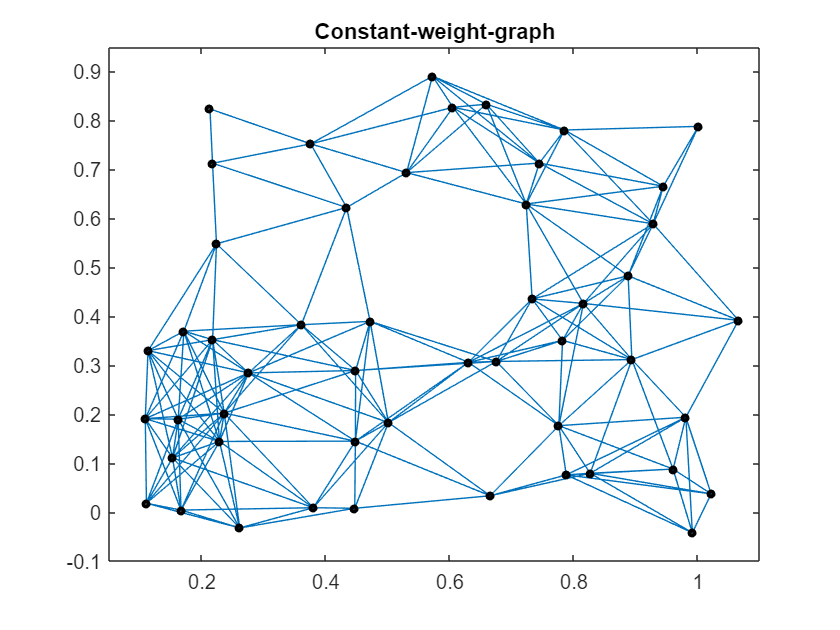


Fig1 = figure(); clf;
gplot(L_unif,xy); % edges
hold on;
plot(xy(:,1), xy(:,2), 'ko','LineWidth',2, 'MarkerSize',2.5); % Points [Nodes]
axis([0.05 1.1 -0.1 0.95]);
title('Constant-weight-graph')

## plot topology of optimal weight graph

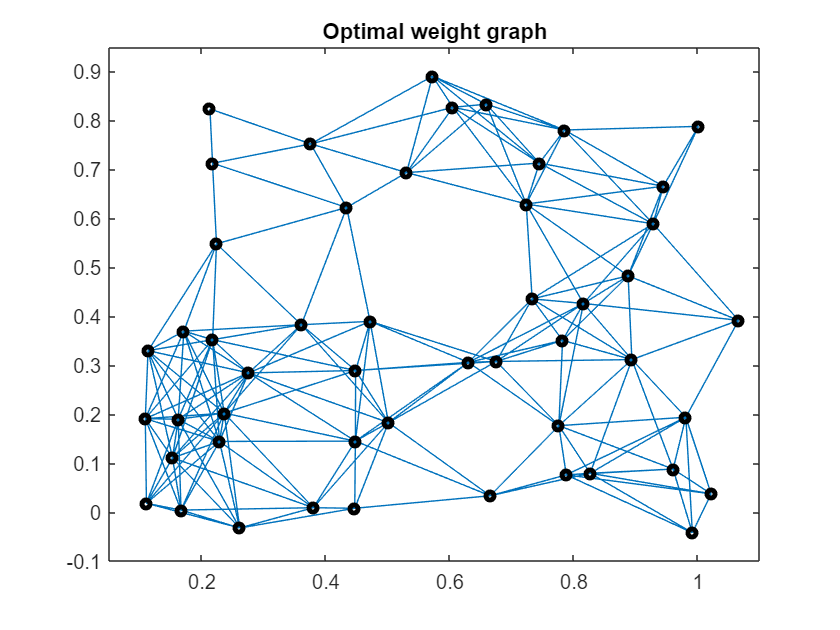


Fig2 = figure(2); clf;
gplot(L,xy);
hold on;
plot(xy(:,1), xy(:,2), 'ko','LineWidth',2.5, 'MarkerSize',4);
axis([0.05 1.1 -0.1 0.95]);
title('Optimal weight graph')

## plot optimal weight graph with edge thickness proportional to weight

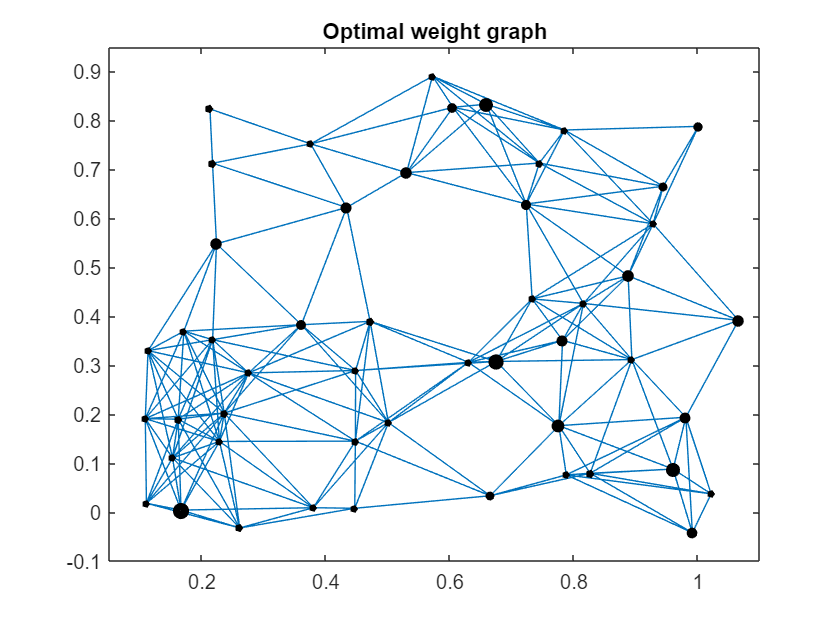

Fig5 = figure(); clf;
gplot(L,xy);
hold on;
for i=1:length(L)
plot(xy(i,1), xy(i,2), 'ko','LineWidth',4, 'MarkerSize',abs(w(i)*4/max(w))+0.1);
end
axis([0.05 1.1 -0.1 0.95]);
title('Optimal weight graph')

## Sparsity Pattern of A:

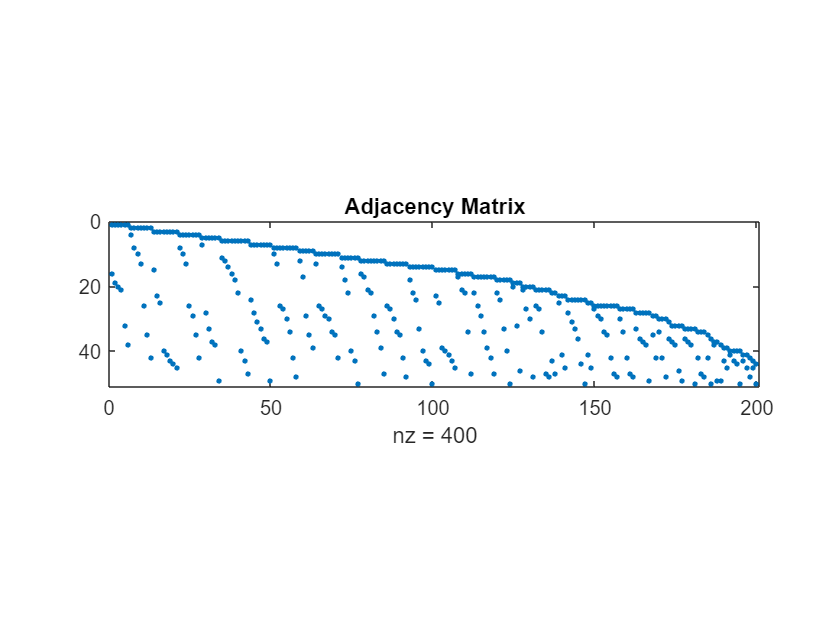

spy(A)
title('Adjacency Matrix')

s = find(A_full > 0.5);
t = find(A_full < -0.5);
g = digraph(s,t,w)

g =   digraph with properties:

    Edges: [200×2 table]
    Nodes: [10000×0 table]


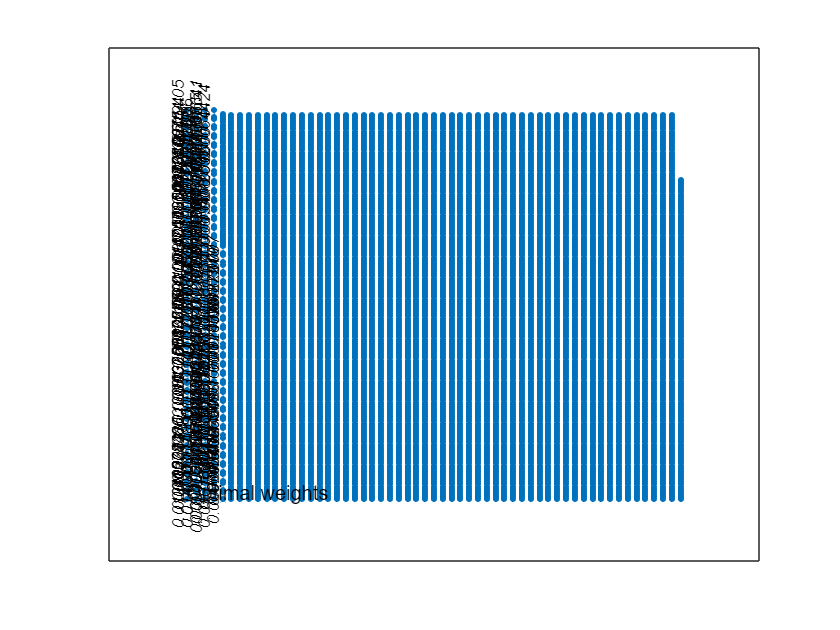

plot(g,'EdgeLabel',g.Edges.Weight)
text(0.3,1.05,'Optimal weights')